**PRÁCTICA 2**

**Nombre: **Juan Mateo Quisilema Flores

**FECHA: **03 de Enero de 2024

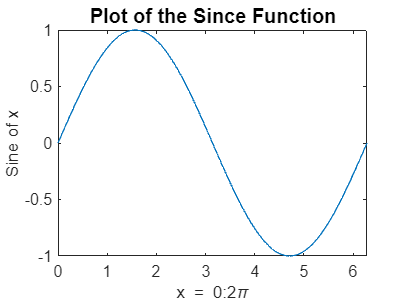

x = 0:pi/100:2*pi;
y = sin (x);
plot(x,y)

xlabel('x = 0:2\pi')
ylabel('Sine of x')
title('Plot of the Since Function','FontSize',12)

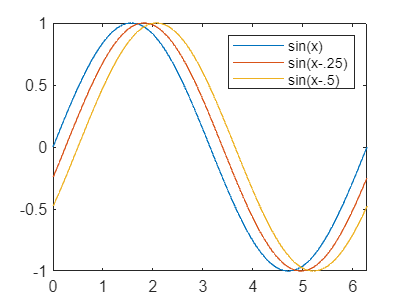

y2 = sin(x-.25);
y3 = sin(x-.5);
plot(x,y,x,y2,x,y3)
legend('sin(x)', 'sin(x-.25)', 'sin(x-.5)')

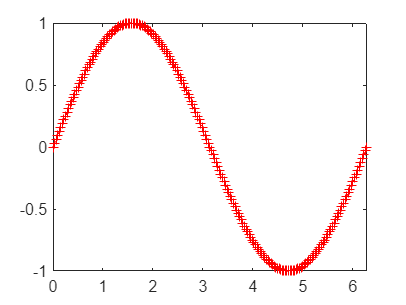

%plot(x,y,'color_style_marker')
plot(x,y,'r:+')

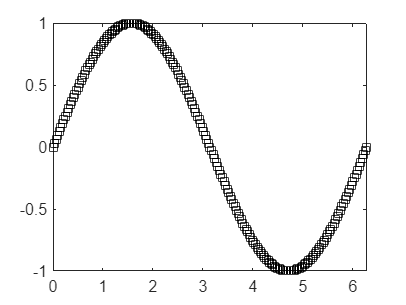


plot(x,y,'ks')

plot(x,y,'r:+')

x1 = 0:pi/100:2*pi;
x2 = 0:pi/100:2*pi;
plot(x1,sin(x1),'r:',x2,sin(x2),'r+')

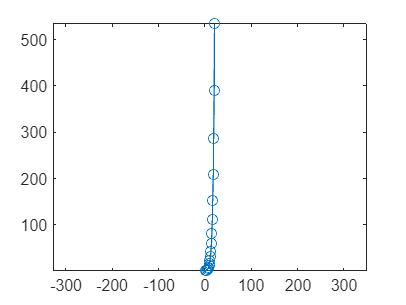

%plot(Z)
%plot(real(Z),imag(Z))
t = 0:pi/10:2*pi;
plot(exp(t),'-o')
axis equal

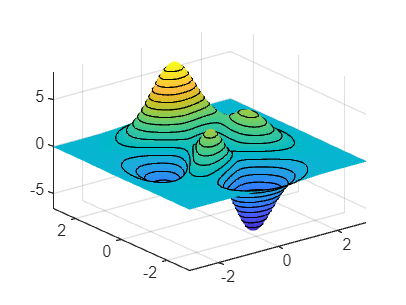

[x,y,z] = peaks;
%Create surface plot
surf(x,y,z)
%Remove edge lines a smooth colors
shading interp
%hold the current graph
hold on 
%add the contour graph to the pcolor graph
contour3 (x,y,z,20,'k')
%return to default 
hold off

%x = 0:pi/20:2*pi;
%subplot(3,1,1); plot (sin(x))
%subplot(3,1,2); plot (cos(x))
%subplot(3,1,3); plot (sin(x).*cos(x))

%t = -pi:pi/100:pi;
%y = sin(t);
%plot(t,y)

%axis([-pi pi -1 1])
%xlabel('-\pi \leq {\itt} \leq \pi')
%ylabel('sin(t)')
%title('Graph of the sine function')
%text(0.5,-1/3,'{\itNote the odd symmetry.}');

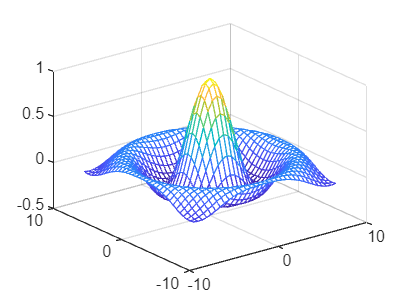

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
mesh(X,Y,Z)

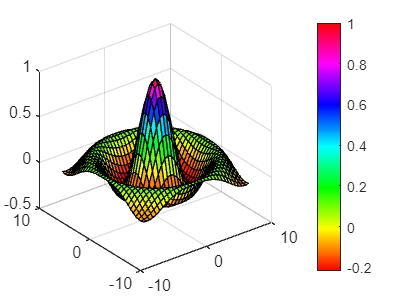

 [X,Y] = meshgrid(-8:.5:8);
 R = sqrt(X.^2 + Y.^2) + eps;
 Z = sin(R)./R;
 surf(X,Y,Z)
 colormap hsv
 colorbar

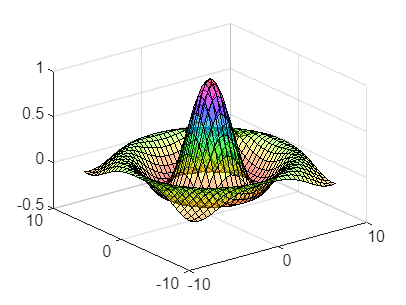

  [X,Y] = meshgrid(-8:.5:8);
 R = sqrt(X.^2 + Y.^2) + eps;
 Z = sin(R)./R;
 surf(X,Y,Z)
 colormap hsv
 alpha(.4)

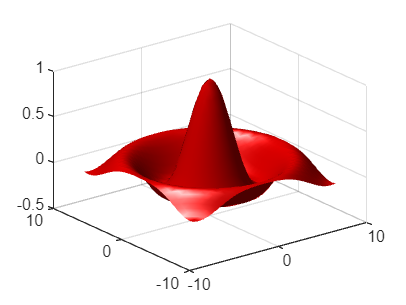

 [X,Y] = meshgrid(-8:.5:8);
 R = sqrt(X.^2 + Y.^2) + eps;
 Z = sin(R)./R;
 surf(X,Y,Z,'FaceColor','red','EdgeColor','none')
 camlight left; 
lighting phong

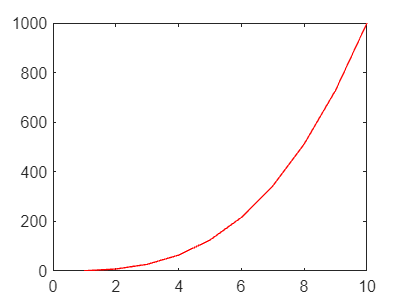

 x = 1:10;
 y = x.^3;
 h = plot(x,y);
 h.Color = 'red';

 h = plot(x,y,'Color','red');

 h.LineWidth

ans = 0.5000

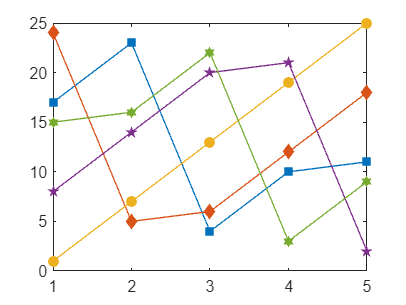

 y = magic(5);
 h = plot(y);
 prop_name(1) = {'Marker'};
 prop_name(2) = {'MarkerFaceColor'};

  prop_values(1,1) = {'s'};
 prop_values(1,2) = {h(1).Color};
 prop_values(2,1) = {'d'};
 prop_values(2,2) = {h(2).Color};
 prop_values(3,1) = {'o'};
 prop_values(3,2) = {h(3).Color};
 prop_values(4,1) = {'p'};
 prop_values(4,2) = {h(4).Color};
 prop_values(5,1) = {'h'};
 prop_values(5,2) = {h(5).Color};

  set(h,prop_name,prop_values)

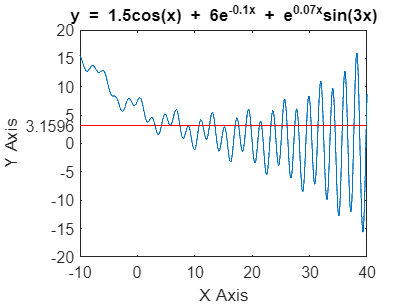

   x = -10:.005:40;
 plotFunc(x)

  function plotFunc(x)
   y = 1.5*cos(x) + 6*exp(-.1*x) + exp(.07*x).*sin(3*x);
   ym = mean(y);
   hfig = figure('Name','Function and Mean');
   hax = axes('Parent',hfig);
   plot(hax,x,y)
   hold on
   plot(hax,[min(x) max(x)],[ym ym],'Color','red')
   hold off
   ylab = hax.YTick;
   new_ylab = sort([ylab, ym]);
   hax.YTick = new_ylab;
   title ('y = 1.5cos(x) + 6e^{-0.1x} + e^{0.07x}sin(3x)')
   xlabel('X Axis')
   ylabel('Y Axis')
   end
